# Numerical Methods for IVP & BVP

By Shohan093

## $\bigcirc$Euler's Method:

#### Question: Use Euler's method to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of t
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% applying Euler's method
for i = 1 : length(t_val) - 1
    y_val(i + 1) = y_val(i) + step * dydt(t_val(i), y_val(i));
end

% displaying the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.2f \ty: %0.7f\t exact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.00 	y: 0.5000000	 exact: 0.5000000	error: 0.0000000
t: 0.10 	y: 0.6500000	 exact: 0.6574145	error: 0.0074145
t: 0.20 	y: 0.8140000	 exact: 0.8292986	error: 0.0152986
t: 0.30 	y: 0.9914000	 exact: 1.0150706	error: 0.0236706
t: 0.40 	y: 1.1815400	 exact: 1.2140877	error: 0.0325477
t: 0.50 	y: 1.3836940	 exact: 1.4256394	error: 0.0419454
t: 0.60 	y: 1.5970634	 exact: 1.6489406	error: 0.0518772
t: 0.70 	y: 1.8207697	 exact: 1.8831236	error: 0.0623539
t: 0.80 	y: 2.0538467	 exact: 2.1272295	error: 0.0733828
t: 0.90 	y: 2.2952314	 exact: 2.3801984	error: 0.0849671
t: 1.00 	y: 2.5437545	 exact: 2.6408591	error: 0.0971046
t: 1.10 	y: 2.7981300	 exact: 2.9079170	error: 0.1097870
t: 1.20 	y: 3.0569430	 exact: 3.1799415	error: 0.1229986
t: 1.30 	y: 3.3186373	 exact: 3.4553517	error: 0.1367144
t: 1.40 	y: 3.5815010	 exact: 3.7324000	error: 0.1508990
t: 1.50 	y: 3.8436511	 exact: 4.0091555	error: 0.1655044
t: 1.60 	y: 4.1030162	 exact: 4.2834838	error: 0.1804676
t: 1.70 	y: 4.3573178	 exact: 4

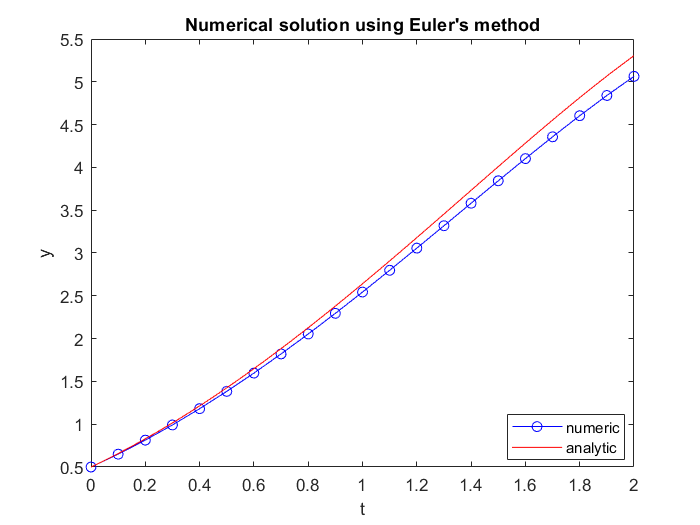


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Euler''s method');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

## $\bigcirc$Modified Euler's Method:

#### Question: Use Euler's modified method to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of t
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% applying Modified Euler's method
for i = 1 : length(t_val) - 1
    % estimating slope at the next point using Euler's Method
    slope = dydt(t_val(i), y_val(i));
    % using the estimated slop to predict the next point
    y_estimate = y_val(i) + step * slope;
    % calculate the slope at the next point based on estimate
    slope_estimate = dydt(t_val(i) + step, y_estimate);
    % updating y_val using average slope
    y_val(i + 1) = y_val(i) + 0.5 * step * (slope + slope_estimate);
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.2f \ty: %0.07f\texact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.00 	y: 0.5000000	exact: 0.5000000	error: 0.0000000
t: 0.10 	y: 0.6570000	exact: 0.6574145	error: 0.0004145
t: 0.20 	y: 0.8284350	exact: 0.8292986	error: 0.0008636
t: 0.30 	y: 1.0137207	exact: 1.0150706	error: 0.0013499
t: 0.40 	y: 1.2122113	exact: 1.2140877	error: 0.0018763
t: 0.50 	y: 1.4231935	exact: 1.4256394	error: 0.0024458
t: 0.60 	y: 1.6458789	exact: 1.6489406	error: 0.0030617
t: 0.70 	y: 1.8793961	exact: 1.8831236	error: 0.0037275
t: 0.80 	y: 2.1227827	exact: 2.1272295	error: 0.0044468
t: 0.90 	y: 2.3749749	exact: 2.3801984	error: 0.0052235
t: 1.00 	y: 2.6347973	exact: 2.6408591	error: 0.0060618
t: 1.10 	y: 2.9009510	exact: 2.9079170	error: 0.0069660
t: 1.20 	y: 3.1720009	exact: 3.1799415	error: 0.0079407
t: 1.30 	y: 3.4463609	exact: 3.4553517	error: 0.0089907
t: 1.40 	y: 3.7222788	exact: 3.7324000	error: 0.0101212
t: 1.50 	y: 3.9978181	exact: 4.0091555	error: 0.0113373
t: 1.60 	y: 4.2708390	exact: 4.2834838	error: 0.0126448
t: 1.70 	y: 4.5389771	exact: 4.5530263	error: 0.

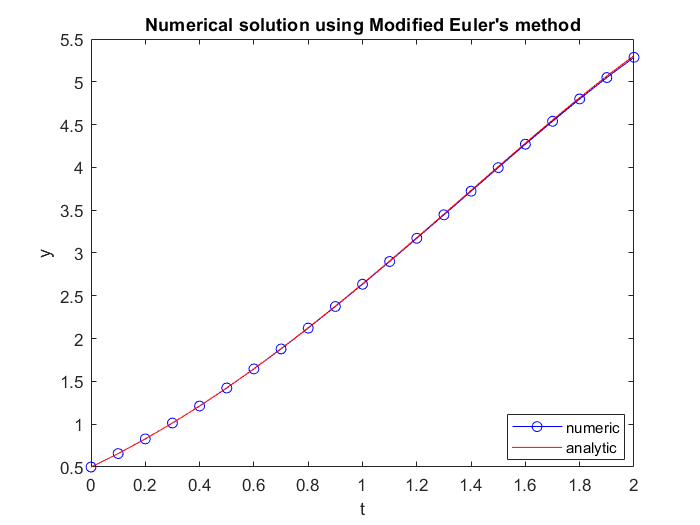


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Modified Euler''s method');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

## $\bigcirc$Runge-Kutta Method:

## Second Order

#### Question: Use Runge-Kutta of second order to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all;

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of x
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% applying Runge-Kutta of fourth order
for i = 1 : length(t_val) - 1
    k1 = step * dydt(t_val(i), y_val(i));
    k2 = step * dydt(t_val(i) + step, y_val(i) + k1);
    y_val(i + 1) = y_val(i) + (k1 + k2) / 2;
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.2f \ty: %0.07f\texact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.00 	y: 0.5000000	exact: 0.5000000	error: 0.0000000
t: 0.10 	y: 0.6570000	exact: 0.6574145	error: 0.0004145
t: 0.20 	y: 0.8284350	exact: 0.8292986	error: 0.0008636
t: 0.30 	y: 1.0137207	exact: 1.0150706	error: 0.0013499
t: 0.40 	y: 1.2122113	exact: 1.2140877	error: 0.0018763
t: 0.50 	y: 1.4231935	exact: 1.4256394	error: 0.0024458
t: 0.60 	y: 1.6458789	exact: 1.6489406	error: 0.0030617
t: 0.70 	y: 1.8793961	exact: 1.8831236	error: 0.0037275
t: 0.80 	y: 2.1227827	exact: 2.1272295	error: 0.0044468
t: 0.90 	y: 2.3749749	exact: 2.3801984	error: 0.0052235
t: 1.00 	y: 2.6347973	exact: 2.6408591	error: 0.0060618
t: 1.10 	y: 2.9009510	exact: 2.9079170	error: 0.0069660
t: 1.20 	y: 3.1720009	exact: 3.1799415	error: 0.0079407
t: 1.30 	y: 3.4463609	exact: 3.4553517	error: 0.0089907
t: 1.40 	y: 3.7222788	exact: 3.7324000	error: 0.0101212
t: 1.50 	y: 3.9978181	exact: 4.0091555	error: 0.0113373
t: 1.60 	y: 4.2708390	exact: 4.2834838	error: 0.0126448
t: 1.70 	y: 4.5389771	exact: 4.5530263	error: 0.

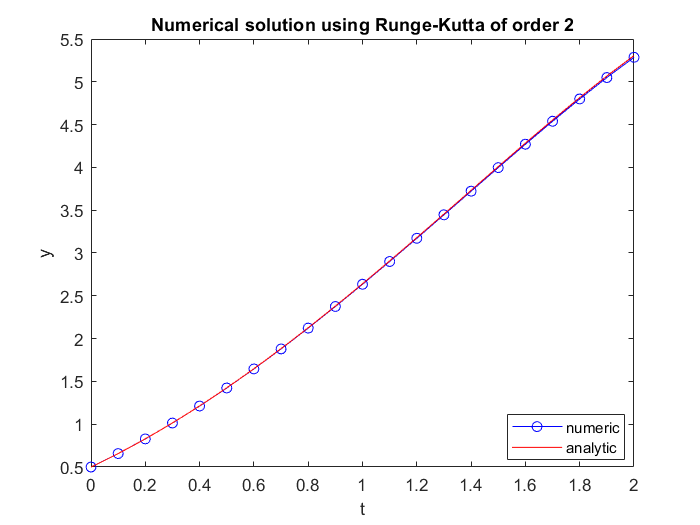


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Runge-Kutta of order 2');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

## Fourth Order

#### Question: Use Runge-Kutta of fourth order to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all;

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of x
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% applying Runge-Kutta of fourth order
for i = 1 : length(t_val) - 1
    k1 = step * dydt(t_val(i), y_val(i));
    k2 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k1 * 0.5);
    k3 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k2 * 0.5);
    k4 = step * dydt(t_val(i + 1), y_val(i) + k3);
    y_val(i + 1) = y_val(i) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.3f \ty: %0.07f\texact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.000 	y: 0.5000000	exact: 0.5000000	error: 0.0000000
t: 0.100 	y: 0.6574144	exact: 0.6574145	error: 0.0000002
t: 0.200 	y: 0.8292983	exact: 0.8292986	error: 0.0000003
t: 0.300 	y: 1.0150701	exact: 1.0150706	error: 0.0000005
t: 0.400 	y: 1.2140869	exact: 1.2140877	error: 0.0000007
t: 0.500 	y: 1.4256384	exact: 1.4256394	error: 0.0000010
t: 0.600 	y: 1.6489394	exact: 1.6489406	error: 0.0000012
t: 0.700 	y: 1.8831222	exact: 1.8831236	error: 0.0000015
t: 0.800 	y: 2.1272278	exact: 2.1272295	error: 0.0000017
t: 0.900 	y: 2.3801964	exact: 2.3801984	error: 0.0000020
t: 1.000 	y: 2.6408567	exact: 2.6408591	error: 0.0000024
t: 1.100 	y: 2.9079143	exact: 2.9079170	error: 0.0000027
t: 1.200 	y: 3.1799385	exact: 3.1799415	error: 0.0000031
t: 1.300 	y: 3.4553482	exact: 3.4553517	error: 0.0000035
t: 1.400 	y: 3.7323961	exact: 3.7324000	error: 0.0000039
t: 1.500 	y: 4.0091511	exact: 4.0091555	error: 0.0000043
t: 1.600 	y: 4.2834790	exact: 4.2834838	error: 0.0000048
t: 1.700 	y: 4.5530210	exact: 4

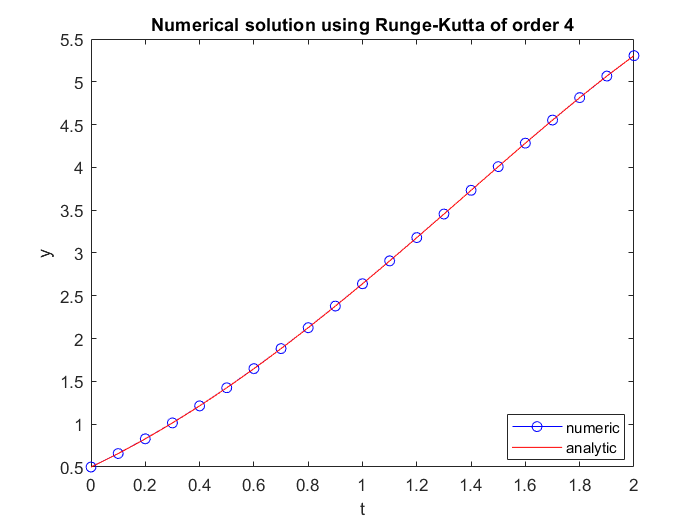


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Runge-Kutta of order 4');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

## $\bigcirc$Multi-Step Method:

### Adams-Bashforth Two-Step

#### Question: Use Adams-Bashforth two-step method to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of x
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% for ABM two-step: 
%   - find the second approximation by using 
%     other methods (i.e RK-4, Euler's)
% using RK-4 to determine previous approximation
k1 = step * dydt(t_val(1), y_val(1));
k2 = step * dydt(t_val(1) + step * 0.5, y_val(1) + k1 * 0.5);
k3 = step * dydt(t_val(1) + step * 0.5, y_val(1) + k2 * 0.5);
k4 = step * dydt(t_val(1 + 1), y_val(1) + k3);
y_val(2) = y_val(1) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;

% applying Adams-Bashforth Two-step
for i = 2 : length(t_val) - 1
    y_val(i + 1) = y_val(i) + 0.5 * step * (3 * dydt(t_val(i), y_val(i)) - dydt(t_val(i - 1), y_val(i - 1)));
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.2f\ty: %0.07f\texact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.00	y: 0.5000000	exact: 0.5000000	error: 0.0000000
t: 0.10	y: 0.6574144	exact: 0.6574145	error: 0.0000002
t: 0.20	y: 0.8295265	exact: 0.8292986	error: 0.0002279
t: 0.30	y: 1.0155848	exact: 1.0150706	error: 0.0005142
t: 0.40	y: 1.2149462	exact: 1.2140877	error: 0.0008585
t: 0.50	y: 1.4269089	exact: 1.4256394	error: 0.0012695
t: 0.60	y: 1.6506979	exact: 1.6489406	error: 0.0017573
t: 0.70	y: 1.8854571	exact: 1.8831236	error: 0.0023335
t: 0.80	y: 2.1302408	exact: 2.1272295	error: 0.0030113
t: 0.90	y: 2.3840041	exact: 2.3801984	error: 0.0038056
t: 1.00	y: 2.6455926	exact: 2.6408591	error: 0.0047336
t: 1.10	y: 2.9137313	exact: 2.9079170	error: 0.0058144
t: 1.20	y: 3.1870114	exact: 3.1799415	error: 0.0070699
t: 1.30	y: 3.4638766	exact: 3.4553517	error: 0.0085249
t: 1.40	y: 3.7426075	exact: 3.7324000	error: 0.0102074
t: 1.50	y: 4.0213048	exact: 4.0091555	error: 0.0121493
t: 1.60	y: 4.2978701	exact: 4.2834838	error: 0.0143863
t: 1.70	y: 4.5699854	exact: 4.5530263	error: 0.0169591
t: 1.80	y:

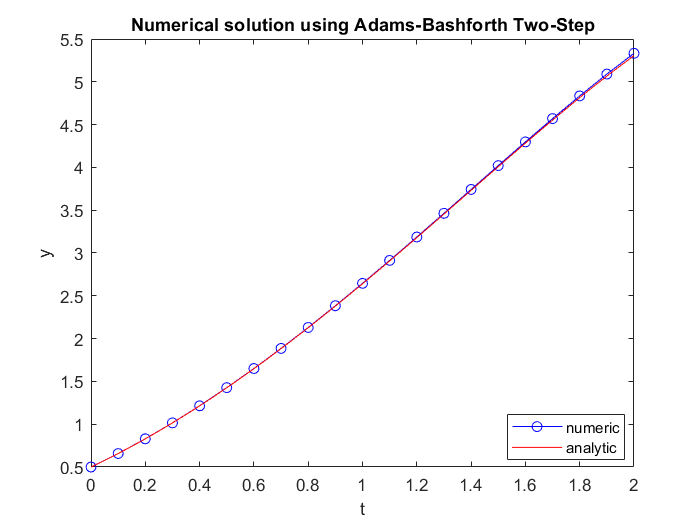


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Adams-Bashforth Two-Step');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

### Adams-Bashforth Three-Step

#### Question: Use Adams-Bashforth three-step method to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of x
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% for ABM three-step: 
%   - find the second and third approximation by using 
%     other methods (i.e RK-4, Euler's)
% using RK-4 to determine previous approximation
for i = 1 : 2
    k1 = step * dydt(t_val(i), y_val(i));
    k2 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k1 * 0.5);
    k3 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k2 * 0.5);
    k4 = step * dydt(t_val(i + 1), y_val(i) + k3);
    y_val(i + 1) = y_val(i) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
end

% applying Adams-Bashforth Three-step
for i = 3 : length(t_val) - 1
    current = dydt(t_val(i), y_val(i));
    one_step_back = dydt(t_val(i - 1), y_val(i - 1));
    two_step_back = dydt(t_val(i - 2), y_val(i - 2));
    y_val(i + 1) = y_val(i) + step / 12 * (23 * current - 16 * one_step_back + 5 * two_step_back);
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.2f\ty: %0.07f\texact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.00	y: 0.5000000	exact: 0.5000000	error: 0.0000000
t: 0.10	y: 0.6574144	exact: 0.6574145	error: 0.0000002
t: 0.20	y: 0.8292983	exact: 0.8292986	error: 0.0000003
t: 0.30	y: 1.0150919	exact: 1.0150706	error: 0.0000213
t: 0.40	y: 1.2141370	exact: 1.2140877	error: 0.0000493
t: 0.50	y: 1.4257217	exact: 1.4256394	error: 0.0000824
t: 0.60	y: 1.6490623	exact: 1.6489406	error: 0.0001217
t: 0.70	y: 1.8832920	exact: 1.8831236	error: 0.0001684
t: 0.80	y: 2.1274531	exact: 2.1272295	error: 0.0002236
t: 0.90	y: 2.3804870	exact: 2.3801984	error: 0.0002885
t: 1.00	y: 2.6412237	exact: 2.6408591	error: 0.0003646
t: 1.10	y: 2.9083705	exact: 2.9079170	error: 0.0004535
t: 1.20	y: 3.1804987	exact: 3.1799415	error: 0.0005571
t: 1.30	y: 3.4560292	exact: 3.4553517	error: 0.0006775
t: 1.40	y: 3.7332171	exact: 3.7324000	error: 0.0008170
t: 1.50	y: 4.0101339	exact: 4.0091555	error: 0.0009784
t: 1.60	y: 4.2846485	exact: 4.2834838	error: 0.0011647
t: 1.70	y: 4.5544056	exact: 4.5530263	error: 0.0013793
t: 1.80	y:

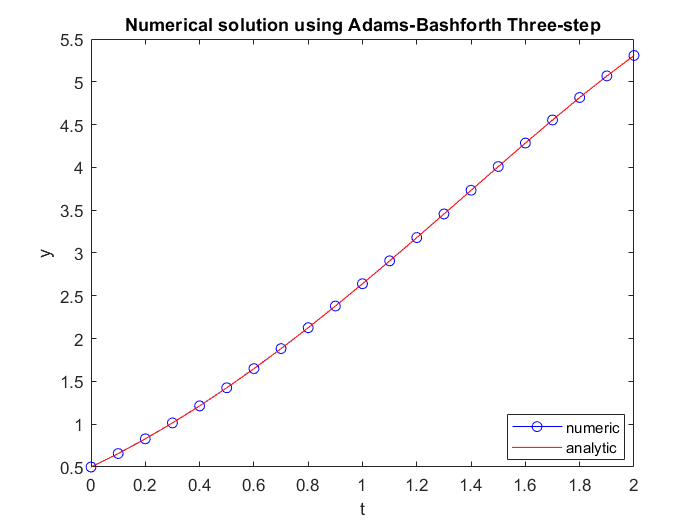


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Adams-Bashforth Three-step');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

### Adams-Bashforth Four-Step

#### Question: Use Adams-Bashforth four-step method to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of x
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% for ABM four-step: 
%   - find the second and third approximation by using 
%     other methods (i.e RK-4, Euler's)
% using RK-4 to determine previous approximation
for i = 1 : 3
    k1 = step * dydt(t_val(i), y_val(i));
    k2 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k1 * 0.5);
    k3 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k2 * 0.5);
    k4 = step * dydt(t_val(i + 1), y_val(i) + k3);
    y_val(i + 1) = y_val(i) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
end

% applying Adams-Bashforth four-step
for i = 4 : length(t_val) - 1
    current = dydt(t_val(i), y_val(i));
    one_step_back = dydt(t_val(i - 1), y_val(i - 1));
    two_step_back = dydt(t_val(i - 2), y_val(i - 2));
    three_step_back = dydt(t_val(i - 3), y_val(i - 3));
    y_val(i + 1) = y_val(i) + step / 24 * (55 * current - 59 * one_step_back + 37 * two_step_back - 9 * three_step_back);
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.2f\ty: %0.07f\texact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.00	y: 0.5000000	exact: 0.5000000	error: 0.0000000
t: 0.10	y: 0.6574144	exact: 0.6574145	error: 0.0000002
t: 0.20	y: 0.8292983	exact: 0.8292986	error: 0.0000003
t: 0.30	y: 1.0150701	exact: 1.0150706	error: 0.0000005
t: 0.40	y: 1.2140892	exact: 1.2140877	error: 0.0000015
t: 0.50	y: 1.4256437	exact: 1.4256394	error: 0.0000043
t: 0.60	y: 1.6489480	exact: 1.6489406	error: 0.0000074
t: 0.70	y: 1.8831348	exact: 1.8831236	error: 0.0000112
t: 0.80	y: 2.1272452	exact: 2.1272295	error: 0.0000157
t: 0.90	y: 2.3802195	exact: 2.3801984	error: 0.0000210
t: 1.00	y: 2.6408864	exact: 2.6408591	error: 0.0000273
t: 1.10	y: 2.9079516	exact: 2.9079170	error: 0.0000347
t: 1.20	y: 3.1799848	exact: 3.1799415	error: 0.0000433
t: 1.30	y: 3.4554050	exact: 3.4553517	error: 0.0000533
t: 1.40	y: 3.7324650	exact: 3.7324000	error: 0.0000649
t: 1.50	y: 4.0092339	exact: 4.0091555	error: 0.0000785
t: 1.60	y: 4.2835779	exact: 4.2834838	error: 0.0000941
t: 1.70	y: 4.5531385	exact: 4.5530263	error: 0.0001122
t: 1.80	y:

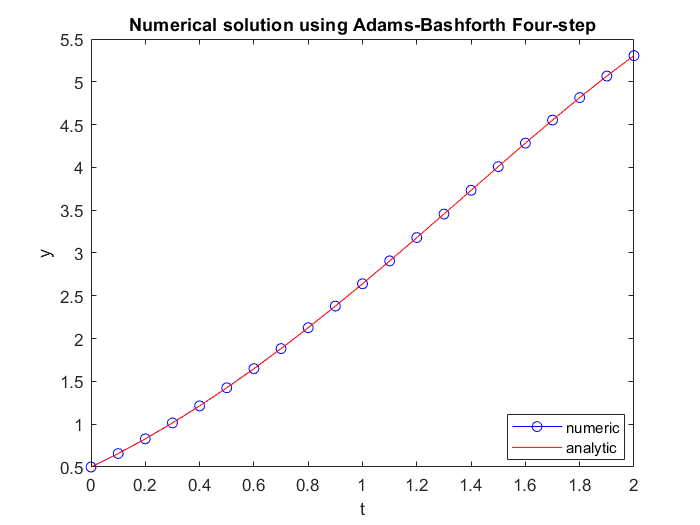


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Adams-Bashforth Four-step');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

### Adams-Moulton Two-Step

#### Question: Use Adams-Moulton Two-step method to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of x
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% for AMM Two-Step method: 
%   - find the necessary approximation by using 
%     other methods (i.e RK-4, Euler's)
% apply Adams-Moulton two-step to update the values
for i = 1 : length(t_val) - 1
    % getting the next value by using RK-4
    k1 = step * dydt(t_val(i), y_val(i));
    k2 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k1 * 0.5);
    k3 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k2 * 0.5);
    k4 = step * dydt(t_val(i + 1), y_val(i) + k3);
    y_val(i + 1) = y_val(i) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    
    % applying the Adams-Moulton of Two-Step to update
    if(i > 2)
        one_step_ahead = dydt(t_val(i + 1), y_val(i + 1));
        current = dydt(t_val(i), y_val(i));
        one_step_back = dydt(t_val(i - 1), y_val(i - 1));
        y_val(i + 1) = y_val(i) + step / 12 * (5 * one_step_ahead + 8 * current - one_step_back);
    end
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.2f\ty: %0.07f\texact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.00	y: 0.5000000	exact: 0.5000000	error: 0.0000000
t: 0.10	y: 0.6574144	exact: 0.6574145	error: 0.0000002
t: 0.20	y: 0.8292983	exact: 0.8292986	error: 0.0000003
t: 0.30	y: 1.0150676	exact: 1.0150706	error: 0.0000030
t: 0.40	y: 1.2140815	exact: 1.2140877	error: 0.0000062
t: 0.50	y: 1.4256294	exact: 1.4256394	error: 0.0000100
t: 0.60	y: 1.6489261	exact: 1.6489406	error: 0.0000145
t: 0.70	y: 1.8831037	exact: 1.8831236	error: 0.0000200
t: 0.80	y: 2.1272032	exact: 2.1272295	error: 0.0000263
t: 0.90	y: 2.3801646	exact: 2.3801984	error: 0.0000339
t: 1.00	y: 2.6408164	exact: 2.6408591	error: 0.0000427
t: 1.10	y: 2.9078641	exact: 2.9079170	error: 0.0000529
t: 1.20	y: 3.1798767	exact: 3.1799415	error: 0.0000649
t: 1.30	y: 3.4552729	exact: 3.4553517	error: 0.0000788
t: 1.40	y: 3.7323051	exact: 3.7324000	error: 0.0000949
t: 1.50	y: 4.0090420	exact: 4.0091555	error: 0.0001135
t: 1.60	y: 4.2833488	exact: 4.2834838	error: 0.0001349
t: 1.70	y: 4.5528666	exact: 4.5530263	error: 0.0001597
t: 1.80	y:

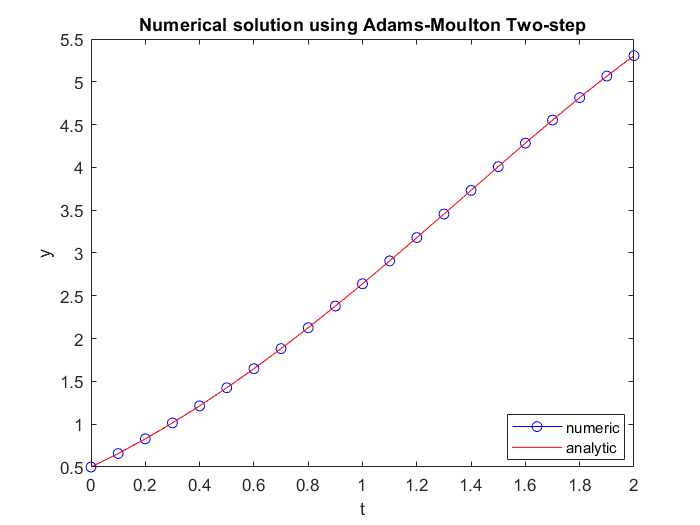


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Adams-Moulton Two-step');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

### Adams-Moulton Three-Step

#### Question: Use Adams-Moulton Three-step method to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of x
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% for AMM Three-Step method: 
%   - find the necessary approximation by using 
%     other methods (i.e RK-4, Euler's)
% apply Adams-Moulton three-step to update the values
for i = 1 : length(t_val) - 1
    % getting the next value by using RK-4
    k1 = step * dydt(t_val(i), y_val(i));
    k2 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k1 * 0.5);
    k3 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k2 * 0.5);
    k4 = step * dydt(t_val(i + 1), y_val(i) + k3);
    y_val(i + 1) = y_val(i) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    
    % applying the Adams-Moulton of Three-Step to update
    if(i > 3)
        one_step_ahead = dydt(t_val(i + 1), y_val(i + 1));
        current = dydt(t_val(i), y_val(i));
        one_step_back = dydt(t_val(i - 1), y_val(i - 1));
        two_step_back = dydt(t_val(i - 2), y_val(i - 2));
        y_val(i + 1) = y_val(i) + step / 24 * (9 * one_step_ahead + 19 * current - 5 * one_step_back + two_step_back);
    end
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.2f\ty: %0.07f\texact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.00	y: 0.5000000	exact: 0.5000000	error: 0.0000000
t: 0.10	y: 0.6574144	exact: 0.6574145	error: 0.0000002
t: 0.20	y: 0.8292983	exact: 0.8292986	error: 0.0000003
t: 0.30	y: 1.0150701	exact: 1.0150706	error: 0.0000005
t: 0.40	y: 1.2140869	exact: 1.2140877	error: 0.0000008
t: 0.50	y: 1.4256383	exact: 1.4256394	error: 0.0000011
t: 0.60	y: 1.6489392	exact: 1.6489406	error: 0.0000014
t: 0.70	y: 1.8831219	exact: 1.8831236	error: 0.0000018
t: 0.80	y: 2.1272273	exact: 2.1272295	error: 0.0000022
t: 0.90	y: 2.3801957	exact: 2.3801984	error: 0.0000028
t: 1.00	y: 2.6408557	exact: 2.6408591	error: 0.0000034
t: 1.10	y: 2.9079129	exact: 2.9079170	error: 0.0000041
t: 1.20	y: 3.1799366	exact: 3.1799415	error: 0.0000049
t: 1.30	y: 3.4553458	exact: 3.4553517	error: 0.0000058
t: 1.40	y: 3.7323931	exact: 3.7324000	error: 0.0000069
t: 1.50	y: 4.0091473	exact: 4.0091555	error: 0.0000082
t: 1.60	y: 4.2834742	exact: 4.2834838	error: 0.0000096
t: 1.70	y: 4.5530150	exact: 4.5530263	error: 0.0000113
t: 1.80	y:

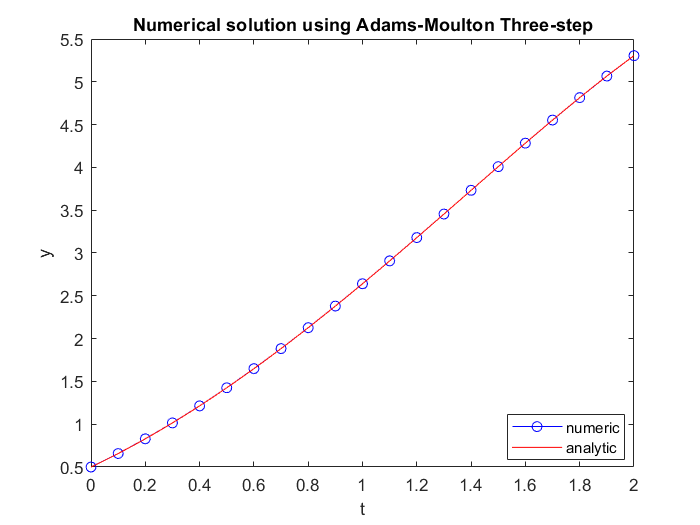


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Adams-Moulton Three-step');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

### Adams-Moulton Four-Step

#### Question: Use Adams-Moulton Four-step method to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of x
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_val = zeros(size(t_val));
y_val(1) = y0;

% for AMM Four-Step method: 
%   - find the necessary approximation by using 
%     other methods (i.e RK-4, Euler's)
% apply Adams-Moulton Four-step to update the values
for i = 1 : length(t_val) - 1
    % getting the next value by using RK-4
    k1 = step * dydt(t_val(i), y_val(i));
    k2 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k1 * 0.5);
    k3 = step * dydt(t_val(i) + step * 0.5, y_val(i) + k2 * 0.5);
    k4 = step * dydt(t_val(i + 1), y_val(i) + k3);
    y_val(i + 1) = y_val(i) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    
    % applying the Adams-Moulton of Four-Step to update
    if(i > 4)
        one_step_ahead = dydt(t_val(i + 1), y_val(i + 1));
        current = dydt(t_val(i), y_val(i));
        one_step_back = dydt(t_val(i - 1), y_val(i - 1));
        two_step_back = dydt(t_val(i - 2), y_val(i - 2));
        three_step_back = dydt(t_val(i - 3), y_val(i - 3));
        y_val(i + 1) = y_val(i) + step / 720 * (251 * one_step_ahead + 646 * current - 264 * one_step_back + 106 * two_step_back - 19 * three_step_back);
    end
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_val(i));
    fprintf("t: %0.2f\ty: %0.07f\texact: %0.7f\terror: %0.7f\n", t_val(i), y_val(i), exact, err);
end

t: 0.00	y: 0.5000000	exact: 0.5000000	error: 0.0000000
t: 0.10	y: 0.6574144	exact: 0.6574145	error: 0.0000002
t: 0.20	y: 0.8292983	exact: 0.8292986	error: 0.0000003
t: 0.30	y: 1.0150701	exact: 1.0150706	error: 0.0000005
t: 0.40	y: 1.2140869	exact: 1.2140877	error: 0.0000007
t: 0.50	y: 1.4256385	exact: 1.4256394	error: 0.0000008
t: 0.60	y: 1.6489396	exact: 1.6489406	error: 0.0000010
t: 0.70	y: 1.8831226	exact: 1.8831236	error: 0.0000011
t: 0.80	y: 2.1272283	exact: 2.1272295	error: 0.0000012
t: 0.90	y: 2.3801971	exact: 2.3801984	error: 0.0000014
t: 1.00	y: 2.6408576	exact: 2.6408591	error: 0.0000015
t: 1.10	y: 2.9079153	exact: 2.9079170	error: 0.0000017
t: 1.20	y: 3.1799396	exact: 3.1799415	error: 0.0000019
t: 1.30	y: 3.4553495	exact: 3.4553517	error: 0.0000022
t: 1.40	y: 3.7323976	exact: 3.7324000	error: 0.0000024
t: 1.50	y: 4.0091528	exact: 4.0091555	error: 0.0000027
t: 1.60	y: 4.2834808	exact: 4.2834838	error: 0.0000030
t: 1.70	y: 4.5530229	exact: 4.5530263	error: 0.0000034
t: 1.80	y:

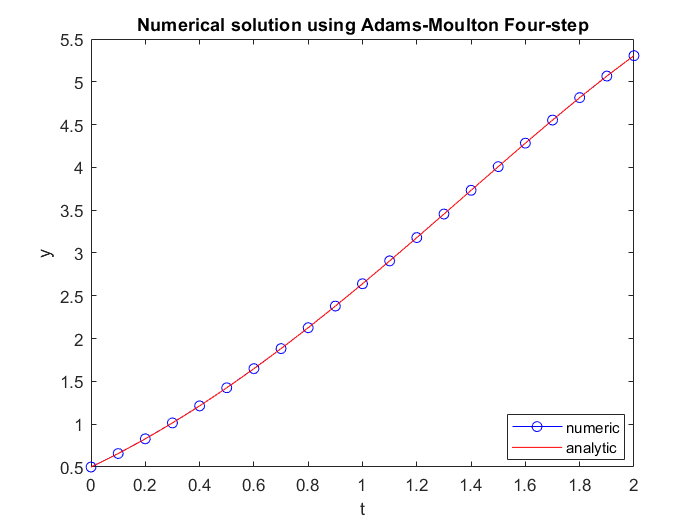


% plotting both the solutions
plot(t_val, y_val, 'b-o');
xlabel('t');
ylabel('y');
hold on;
fplot(sol, [0, 2], 'r'); % for exact solution
title('Numerical solution using Adams-Moulton Four-step');
legend('numeric', 'analytic', 'Location', 'best');
hold off;

## $\bigcirc$Predator-Corrector using Adams formulae:

#### Question: Use Adams-Bashforth Four-step method and Adams-Moulton Three-Step method to approximate the solutions of $$y' = y^2 - t + 1$ with $y(0) = 0.5$ for $0 \leq t \leq 2$$.

*Solution Code:*

clear all

% exact solution
syms x;
sol = (x + 1)^2 - exp(x) * 0.5;

% defining the ODE y' = y - t^2 + 1
dydt = @(t, y) y - t^2 + 1;

% defining the initial conditions
t0 = 0;
y0 = 0.5;

% defining the final value of x
t_final = 2;

% step size
step = 0.1;

% initialinzing the arrays to store the variables
t_val = t0 : step : t_final;
y_predator = zeros(size(t_val));
y_corrector = zeros(size(t_val));
y_predator(1) = y0;
y_corrector(1) = y0;

for i = 1 : length(t_val) - 1
    % getting the next value by using RK-4
    k1 = step * dydt(t_val(i), y_predator(i));
    k2 = step * dydt(t_val(i) + step * 0.5, y_predator(i) + k1 * 0.5);
    k3 = step * dydt(t_val(i) + step * 0.5, y_predator(i) + k2 * 0.5);
    k4 = step * dydt(t_val(i + 1), y_predator(i) + k3);
    y_predator(i + 1) = y_predator(i) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    y_corrector(i + 1) = y_predator(i + 1);
    
    % predicting the values
    if (i > 3)
        current = dydt(t_val(i), y_predator(i));
        one_step_back = dydt(t_val(i - 1), y_predator(i - 1));
        two_step_back = dydt(t_val(i - 2), y_predator(i - 2));
        three_step_back = dydt(t_val(i - 3), y_predator(i - 3));
        y_predator(i + 1) = y_predator(i) + step / 24 * (55 * current - 59 * one_step_back + 37 * two_step_back - 9 * three_step_back);
    end
    
    % updating the values
    if(i > 3)
        one_step_ahead = y_predator(i + 1);
        current = dydt(t_val(i), y_predator(i));
        one_step_back = dydt(t_val(i - 1), y_predator(i - 1));
        two_step_back = dydt(t_val(i - 2), y_predator(i - 2));
        y_corrector(i + 1) = y_predator(i) + step / 24 * (9 * one_step_ahead + 19 * current - 5 * one_step_back + two_step_back);
    end
end

% printing the approximations
for i = 1 : length(t_val)
    exact = subs(sol, x, t_val(i));
    err = abs(exact - y_corrector(i));
    fprintf('Predicted y: %0.7f\tCorrected y: %0.7f\texact: %0.7f\tError: %0.7f\n', y_predator(i), y_corrector(i), exact, err);
end

Predicted y: 0.5000000	Corrected y: 0.5000000	exact: 0.5000000	Error: 0.0000000
Predicted y: 0.6574144	Corrected y: 0.6574144	exact: 0.6574145	Error: 0.0000002
Predicted y: 0.8292983	Corrected y: 0.8292983	exact: 0.8292986	Error: 0.0000003
Predicted y: 1.0150701	Corrected y: 1.0150701	exact: 1.0150706	Error: 0.0000005
Predicted y: 1.2140892	Corrected y: 1.1825870	exact: 1.2140877	Error: 0.0315007
Predicted y: 1.4256437	Corrected y: 1.3975160	exact: 1.4256394	Error: 0.0281234
Predicted y: 1.6489480	Corrected y: 1.6249453	exact: 1.6489406	Error: 0.0239953
Predicted y: 1.8831348	Corrected y: 1.8640068	exact: 1.8831236	Error: 0.0191169
Predicted y: 2.1272452	Corrected y: 2.1137418	exact: 2.1272295	Error: 0.0134877
Predicted y: 2.3802195	Corrected y: 2.3730907	exact: 2.3801984	Error: 0.0071078
Predicted y: 2.6408864	Corrected y: 2.6408822	exact: 2.6408591	Error: 0.0000231
Predicted y: 2.9079516	Corrected y: 2.9158220	exact: 2.9079170	Error: 0.0079050
Predicted y: 3.1799848	Corrected y: 3.19

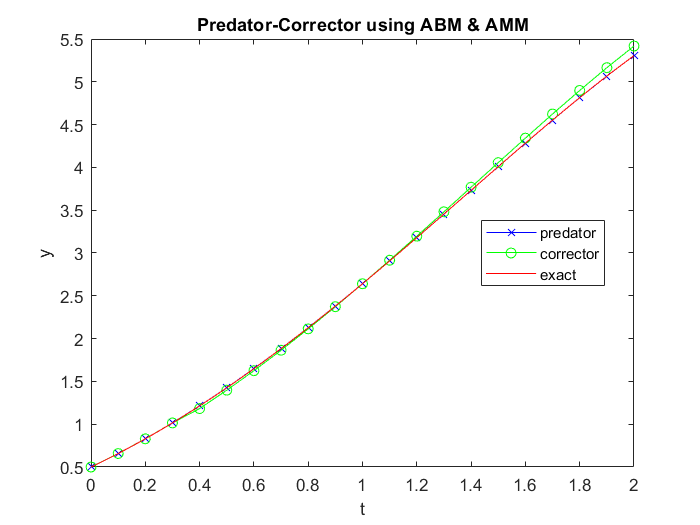


% plotting the approximations
plot(t_val, y_predator, 'b-x');
hold on;
plot(t_val, y_corrector, 'g-o');
fplot(sol, [0, 2], 'r'); % for exact solution
title('Predator-Corrector using ABM & AMM');
xlabel('t');
ylabel('y');
legend('predator', 'corrector', 'exact', 'Location', "best");
hold off;